# **Introduction to Hypergraph Analysis Toolbox (HAT)**

This file introduces the most basics elements of HAT in the MATLAB distribution:

- Construction

- Visualization

- Tensor Representation

- Expansion

For a more comprehensive view of HAT's capabilities and additional tutorials see [1] and [https://hypergraph-analysis-toolbox.readthedocs.io/](https://hypergraph-analysis-toolbox.readthedocs.io/)

## Hypergraph Construction

IM = [1 1 0;                % Incidence Matrix
      1 1 0;
      1 0 1;
      0 1 1;
      0 0 1];
HG1 = Hypergraph('IM',IM)    % Hypergraph object

## Visualization

HG1.plot();                  % Plotting command 
title('Incidence Matrix v1'); xlabel('Hyperedges'); ylabel('Vertices');
set(gca,'XTick',[]); set(gca,'YTick',[])

HAT.plotIncidenceMatrix(HG1, '*', {'r', 'b', 'g'}); % Plotting command 2
title('Incidence Matrix v2'); xlabel('Hyperedges'); ylabel('Vertices')
set(gca,'XTick',[]); set(gca,'YTick',[]);

## Random k-uniform hypergraphs

v = 10;     % Number of vertices
e = 20;     % Number of hyperedges
k = 4;      % Size of hyperedges

HG2 = HAT.uniformErdosRenyi(v, e, k);

HG2.plot();
title('Incidence Matrix'); xlabel('Hyperedges'); ylabel('Vertices')
set(gca,'XTick',[]); set(gca,'YTick',[]);

## Tensor Representation

HAT represents uniform hypergraphs as tensors according to definitions in [1]. The adjacency tensor of a uniform hypergraph is defined:

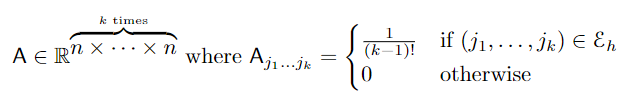

To access the adjacency tensor in HAT, the following command is used:

A = HG1.adjTensor

A tensor analogue of the degree matrix is provided as well:

D = HG1.degreeTensor

The Laplacian tensor is defined as **D - A** and may be computed two ways:

L1 = D - A;                 % Method 1
L2 = HG1.laplacianTensor    % Method 2

## Expansion

Hypergraphs can be expanded to pairwise graph structures. Clique and star expansion are two of the most common expansions.

C = HG1.cliqueGraph;
plot(graph(C)); title('Clique Expansion')
S = HG1.starGraph;
X = [1 1 1 1 1 0 0 0]';
Y = [0 1 2 3 4 0.5 2 3.5]';
p = plot(graph(S)); title('Star Expansion')
p.XData = X; p.YData = Y;

## References

[1] Joshua Pickard, Can Chen, Rahmy Salman, Cooper Stansbury, Sion Kim, Amit Surana, and Indika Rajapakse. "Hypergraph Analysis Toolbox for Chromosome Conformation."